% function Depth

%%%% ABANDONING THIS WAY OF FINDING DEPTH :)

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat
load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');

power = calibrateBrightness(20240105, 02, 005);

outputBrightness = 1.0e-10 *

    0.0003    0.0003    0.0003    0.0002    0.0002    0.0003    0.0003    0.0004    0.0008    0.0005    0.0007    0.0006    0.0003    0.0002    0.0002    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0003    0.0001    0.0000    0.0000    0.0001


depth = twtt2Depth(twtt, 1.77); % rwo 1 = surface, row 2 = bottom variables

depth = 1.0e+03 *

    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3424    0.3429    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430
    2.6344    2.6347    2.6333    2.6301    2.6275    2.6270    2.6274    2.6282    2.6286    2.6287    2.6293    2.6303    2.6319    2.6336    2.6347    2.6353    2.6355    2.6347    2.6330    2.6301    2.6265    2.6247    2.6237    2.6221    2.6200    2.6174    2.6147    2.6119    2.6095    2.6076    2.6063    2.6053    2.6056    2.6067    2.6098    2.6138    2.6191    2.6226    2.6225    2.6216    2.6207    2.6197    2.6188    2.6159    2.6124    2.6102    2.6087    2.6084


layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20240105_02\Data_20240105_02_005.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

bin = round(Bottom);

a = linspace(1, length(bin), length(bin));
ai = linspace(1, size(depth, 2), size(depth, 2));
interpBin= interp1(a, bin, ai, 'linear', 'extrap')

interpBin =         1665        1664        1661        1660        1661        1661        1662        1664        1665        1665        1663        1659        1658        1656        1653        1650        1648        1647        1648        1652        1657        1657        1656        1655        1651        1649        1649        1650        1651        1651        1651        1651        1653        1658        1660        1662        1665        1667        1673        1680        1683        1688        1690        1690        1691        1690        1690        1689        1689        1688


a = 1:length(Bottom);
newLength = size(depth, 2);
ai = linspace(1, length(a), newLength);
interpBottom = interp1(a, Bottom, ai, 'cubic')

interpBottom = 1.0e+03 *

    1.6648    1.6645    1.6635    1.6616    1.6603    1.6601    1.6603    1.6608    1.6610    1.6610    1.6614    1.6620    1.6631    1.6640    1.6646    1.6649    1.6649    1.6644    1.6633    1.6615    1.6594    1.6585    1.6580    1.6569    1.6557    1.6541    1.6525    1.6509    1.6495    1.6484    1.6476    1.6471    1.6472    1.6481    1.6501    1.6526    1.6556    1.6574    1.6572    1.6568    1.6562    1.6557    1.6551    1.6532    1.6511    1.6498    1.6491    1.6490    1.6492    1.6497


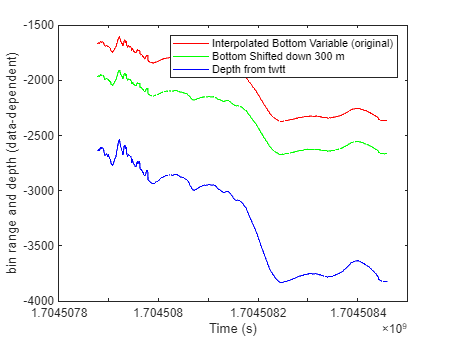

depth(2, :);

plot(gps_time, -interpBottom, 'r')
hold on 
plot(GPS_time, -Bottom-300, 'g')
plot(gps_time, -depth(2, :), 'b')
legend('Interpolated Bottom Variable (original)', 'Bottom Shifted down 300 m', 'Depth from twtt')
hold off
xlabel("Time (s)")
ylabel('bin range and depth (data-dependent)')

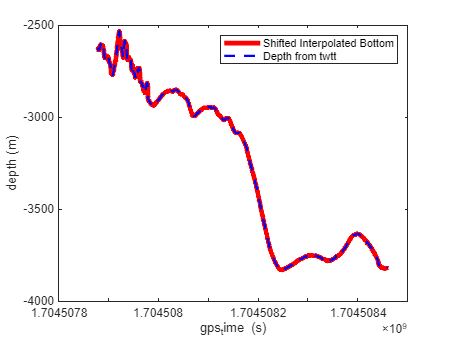

shiftedAmount = depth(2,:) - interpBottom; % amoutn to shift bottom to be equal to depth variable!

plot(gps_time, -interpBottom-shiftedAmount, 'r','LineWidth', 4)
hold on 
plot(gps_time, -depth(2, :), 'b','LineWidth', 2, 'LineStyle', '--')
hold off
legend('Shifted Interpolated Bottom', 'Depth from twtt')
ylabel('depth (m)')
xlabel("gps_time (s)")

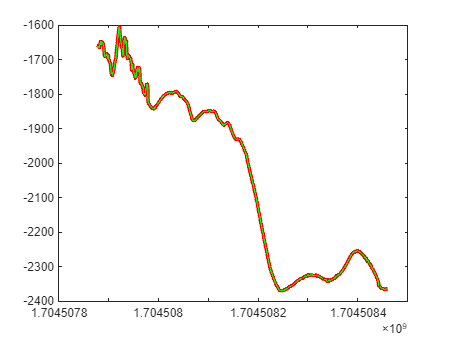

Bin = round(Bottom);

plot(GPS_time, -Bin, 'r', 'LineWidth', 3)
hold on 
plot(GPS_time, -Bottom, 'g')
hold off